# **Comunicações Digitais**

# **Practical Assignment nº 1**

# **MULTISYMBOL SYSTEMS WITH OPTIMUM DETECTION**

# **(2023/2024)**

## 1       Introduction

This assignment aims at studying transmission systems based on optimum detection of multi-symbol signals, using for this purpose the QAM signal. For the assignment it will be used MATLAB with Live Editor, complemented with the corresponding Communications Toolbox.

The assignment will be carried out in **three practical classes**.

Date and time limit for uploading the report and MATLAB scripts: **18-10-2023**.  Reports sent **via email will not be accepted**.

**Note: **When performing simulations to determine error rates, the number of used symbols/bits must be optimized. Thus, the number of symbols/bits in each simulation run should ensure that in 95% of experiments the estimated error probability is within a factor of two from the actual error probability. However, the number of symbols/bits should not be greater than the value necessary to ensure the above requirement for the most demanding case in a given simulation set.

## 2       QAM Signal

The theoretical bases to perform this assignment were studied in detail during the lectures. Therefore, it is strongly recommended the revision of the relevant material (slides, relevant book extracts), available in eLearning and listed in the final part of this script.

### *2.1*      *QAM Transmitter*

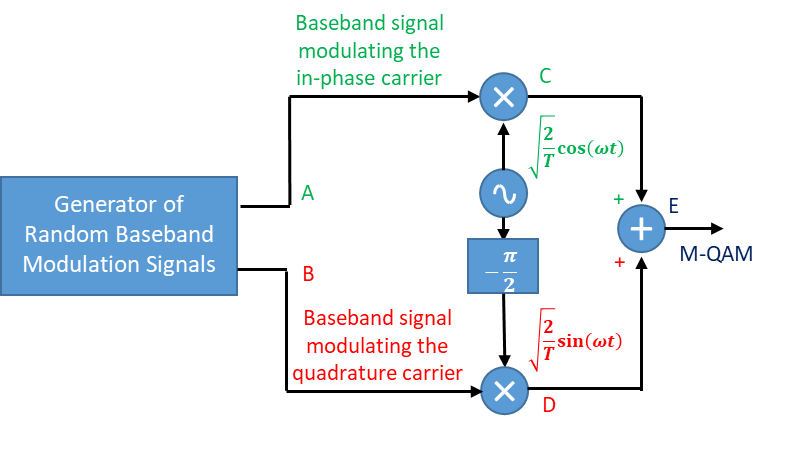

*Figure 1*

Implement a MATLAB function y=*mary(K,d,m,n)* that simulates the baseband signals A and B, represented in Figure 1, that modulate the carriers of quadrature of the QAM.  The signals A and B are of the NRZ type and can take one of the following amplitudes, with equal probability: $\pm d/2$, $\pm 3d/2$, …, $\pm (K-1)d/2$. $d$ is therefore the difference between consecutive levels in the baseband modulating signal, and $K
$ is the number of levels that the signal can assume. The paremeter *m*  is the number of simulated symbols and *n* is the number of samples per symbol. The function is to be defined in the end of the script.

## *2.2*      *Characterization of the transmitted signal *

Considering:

clear all, clf
KI = 8; % Number of in-phase levels
KQ = 8; % Number of quadrature levels
d=1;    % Distance between symbols
m=100e3; % nº of symbols to simulate (m). 
n=100;  % nº of samples per symbol 
sym=3;  % nº of symbols used in time plots (must be smaller than m)

yi = mary(KI,d,m,n);  %KI nº of in-phase levels;      m-nº of symbols to simulate; nº samples per symbol
yq = mary(KQ,d,m,n);  %KQ nº of in-quadrature levels; m-nº of symbols to simulate; nº samples per symbol

Study the main characteristics of the generated QAM signal. For this purpose, proceed as indicated in the following paragraphs.

***(a)***  Draw the complete QAM constellation obtained by simulation, considering the quadrature carriers shown in Figure 2. In this constellation, indicate the points corresponding to the first three simulated symbols. You must indicate these points with the designations symb1, symb2 and symb3, respectively. **The three simulated symbols must be generated randomly.**

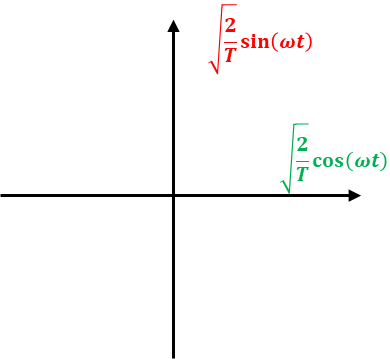

*Figure 2*

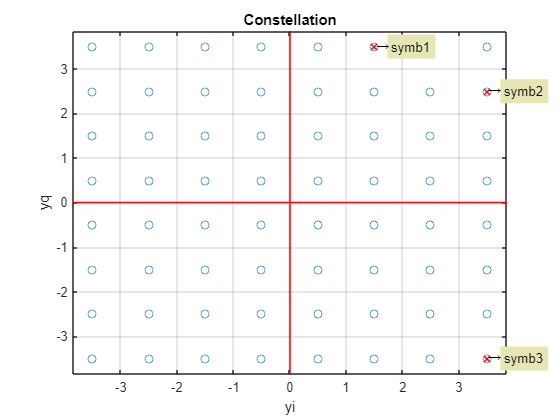

% replace this with your code
% constelação
figure(1)
plot(yi, yq, 'o'), xlabel('yi'), ylabel('yq'), title('Constellation'), grid on

% Ver os símbolos obtidos (aleatoriamente)
hold on
for i=1:sym
    symbol_number=int2str(i);
    plot(yi(i*n), yq(i*n), 'rx', 'LineWidth',1)
    text(0.3+yi(i*n), yq(i*n),['symb', symbol_number],'BackgroundColor',[.9 .9 .7]);
    text(yi(i*n), yq(i*n), '\rightarrow')
end

% Desenho dos eixos 
alpha = 1.1;
Min_i = min(yi); Min_q = min(yq);
Max_i = max(yi); Max_q = max(yq);
axis([alpha*Min_i alpha*Max_i alpha*Min_q alpha*Max_q]);

hold on
% yy axis
yy=[alpha*Min_q alpha*Max_q]; xx=[0 0];
plot(xx,yy, 'r','LineWidth',1) 
    
 % xx axis
yy=[0 0]; xx=[alpha*Min_i alpha*Max_i];
plot(xx,yy, 'r','LineWidth',1)
hold off

### Comments

A constelação criada com **8 níveis na componente em fase (yi) e na componente em quadratura (yq)**, representa uma constelação de **64-QAM**.

Obtivemos um sinal 64-QAM com 64 posições possíveis para a representação dos símbolos presentes no referencial cartesiano com três símbolos aleatórios identificados na constelação. Os símbolos representados estão distanciados d = 1. Cada símbolo consegue enviar 6 bits.

***(b)***  Obtain by simulation the baseband signals that modulate the in-phase (y*i*) and quadrature carriers (y*q*) (signals A and B in Fig. 1), corresponding to the **first three symbols** mentioned in (a). The abscissa scale used in the graphical representation should be **normalized relative to the bit duration**. For the **second and third symbol** intervals, show that the **levels **of the baseband signals are in agreement with the location of the respective symbols in the constellation drawn in (a).

Plot the in-phase baseband signal

% replace this with your code
nbps =  log2(KI*KQ) % número de bits por amostra

nbps = 6

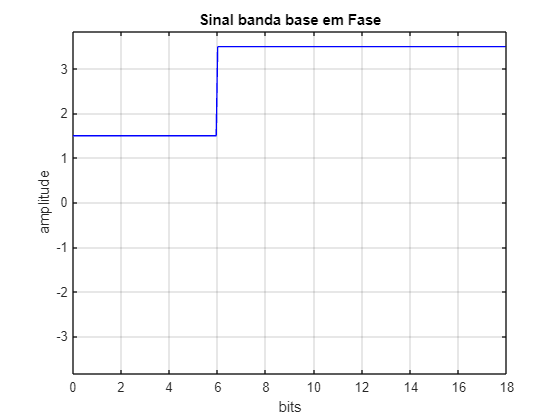

n_sym = (0:sym*n)*nbps/n;
figure(2)
plot(n_sym(1:sym*n), yi(1:sym*n),'b'), title('Sinal banda base em Fase'), xlabel('bits'), ylabel('amplitude'), ylim([-8 8]);
%
Max_n_sym = max(n_sym); Min_n_sym = min(n_sym);
Max_y = max(yi); Min_y = min(yi);
axis([Min_n_sym Max_n_sym alpha*Min_y alpha*Max_y])
grid on

Plot the quadrature baseband signal

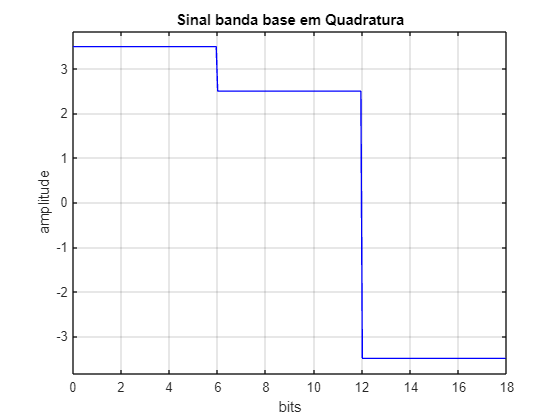

% replace this with your code
% número de bits por símbolo
figure(3)
plot(n_sym(1:sym*n), yq(1:sym*n),'b'), title('Sinal banda base em Quadratura'), xlabel('bits'), ylabel('amplitude')

%
Max_n_sym = max(n_sym); Min_n_sym = min(n_sym);
Max_y = max(yq); Min_y = min(yq);
axis([Min_n_sym Max_n_sym alpha*Min_y alpha*Max_y])
grid on

### Observations

Podemos concluir que os valores de amplitude para os sinais em banda base estão em conformidade com os valores vistos na constelação, sendo que estes variam entre [-7d/2, 7d/2] no caso estudado do 64-QAM.

***(c)  ***Obtain by simulation the two modulated quadrature carriers (signals C and D in Fig. 1) and the QAM modulator output (signal E in Fig. 1), during the time span corresponding to the three symbols mentioned in (a) and (b). The ratio between the carrier frequency and symbol-rate is 4. The abscissa scale should be normalized relative to **bit duration**. The numerical values of the two quadrature carrier amplitudes, corresponding to symbol 3, **are in agreement** with the representation of this symbol in the constellation shown in (a)? **Explain why.**

Plot modulated I carrier

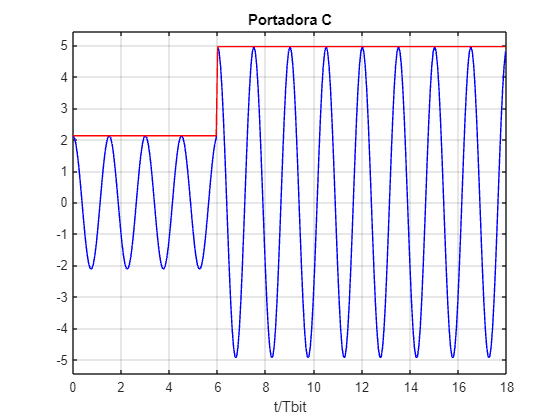

% replace this with your code
Rfs = 4; % frequência da portadora é 4 vezes a taxa de símbolos
i = sqrt(2)*cos(2*pi*Rfs*n_sym/nbps); % gera a portadora em fase (I) com uma frequência de portadora que é 4 vezes a taxa de símbolos
C = i.*yi(1:length(n_sym)); % multiplica a portadora em fase (I) pelo sinal de banda base em fase (yi) para obter o sinal modulado da portadora em fase (C).
figure(3)
plot(n_sym(1:3*n), C(1:3*n),'b'), title('Portadora C'), xlabel('t/Tbit'), grid on

%
a_lim = sqrt(2)*alpha;
axis([Min_n_sym Max_n_sym a_lim*Min_y a_lim*Max_y]);
hold on
plot(n_sym(1:sym*n),sqrt(2)*yi(1:sym*n), 'r')
hold off

Plot modulated Q carrier

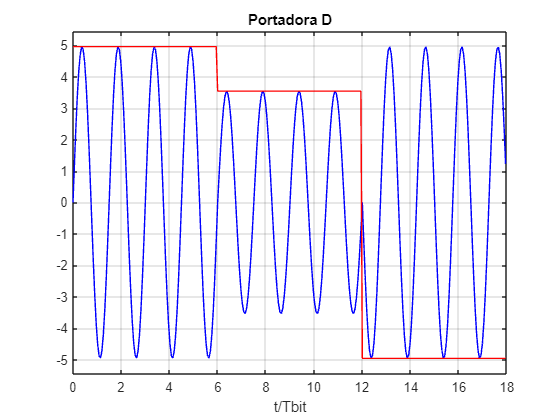

% replace this with your code
i = sqrt(2)*sin(2*pi*Rfs*n_sym/nbps);
D = i.*yq(1:length(n_sym));
figure(4)
plot(n_sym(1:3*n), D(1:3*n),'b'), title('Portadora D'), xlabel('t/Tbit'), grid on

%
a_lim = sqrt(2)*alpha;
axis([Min_n_sym Max_n_sym a_lim*Min_y a_lim*Max_y]);
hold on
plot(n_sym(1:sym*n),sqrt(2)*yq(1:sym*n), 'r')
hold off

### Comments

- Portadora em Fase ( **C **)

Cada símbolo tem 5 períodos da portadora para cumprir o racio.  É uma onda sinusoidal com uma frequência 4 vezes (Rfs = 4) superior que a taxa de símbolos e com amplitude igual ao sinal de banda base em fase ( yi ).

- Portadora em Quadratura ( **D** )

Tal como a portadora em fase, é uma sinousoide com 5 períodos da portadora, igualmente com frequência 4 vezes superior à taxa de símbolos mas com amplitude igual ao sinal de banda base em quadratura ( yq ).

A partir da informação inicial conseguimos determinar o valor de fase. Quando **a sinosoide é positiva a fase é 0 , se for a sinosoide é negativa é pi.**

Podemos notar que os valores numéricos de amplitude da portadora modulada obtida nos pontos C e D é maior do que os valores dos símbolos correspondentes que obtivemos na constelação, isto acontece devido à multiplicação pelas portadores ortonormais (√2). Esta propriedade vai-nos permitir somar as duas portadoras sem as alterar e vai ser igualmente útil na desmodulação.

**(d) **Obtain by simulation the QAM modulator output (signal E in Fig. 1), during the time span corresponding to the 3 symbols mentioned in (a). The abscissa scale must be normalized relative to bit duration. Signal E must be obtained through the addition operation indicated in Fig. 1. Verify that the amplitudes of the modulated carrier correspond to the desired values. 

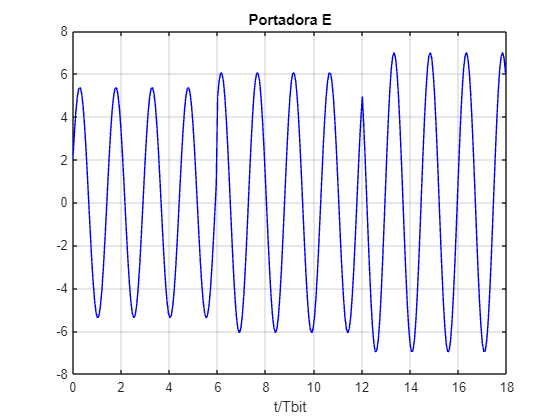

% replace this with your code
E = C + D; % Modelação QAM
plot(n_sym(1:3*n), E(1:3*n), 'b'), title('Portadora E'), xlabel('t/Tbit'), grid on,
axis([Min_n_sym Max_n_sym -8 8]);
hold off

### Observations

- Saída do sinal M-QAM ( **E** ) 

Resultado da soma das portadoras em fase ( **C** ) e em quadratura ( **D** ).

***(e)  *****Obtain the average symbol energy** of the implemented QAM signal**, from the carrier simulated signal in (c) (time domain)**. Compare the values of the average symbol energy obtained by simulation, with the theoretical prediction. Hint: for a square QAM constellations of size $M=2^k$, with $k$ even, the average symbol energy is given by: $E_s = (M-1)\frac{d^2}{6}$ 

% replace this with your code
M = KI*KQ;

Es = (M-1)*d^2/6; % teórico
E_sim = mean(yi.^2 + yq.^2); % prático

fprintf("Energia média (teórica) por símbolo é %g", Es);

Energia média (teórica) por símbolo é 10.5

fprintf("Energia média (prática) por símbolo é %g", E_sim);

Energia média (prática) por símbolo é 10.5195

### **Comments**

A partir dos valores obtidos é possível afirmar que os valores práticos estão bastante próximos dos teóricos, concluindo que a **simulação está de acordo com o valor previsto para a energia média por símbolo ( Es ).**

**(f)** Obtain by simulation the unilateral PSD of the baseband signal, which modulates the in-phase carrier (signal A in Fig. 1). For this purpose, **you must use MATLAB function *****pwelch. ***The frequencies scale must be **normalized relative to the transmission rate of the bits** transported by the QAM signal. The estimated PSD should have a small variance ratio (slightly visible in the graphs). The frequency resolution should originate a very good fit between the experimental curve and theoretical curve (to be drawn later on), in the minima regions.  The xx-axis scale must be chosen to allow proper viewing of the relevant parts of the PSDs including the first two minima. Justify the parameters used in ***pwelch ****function. ***On the same graph** draw the corresponding theoretical curve, using MATLAB.

Simulated and theoretical unilateral PSD

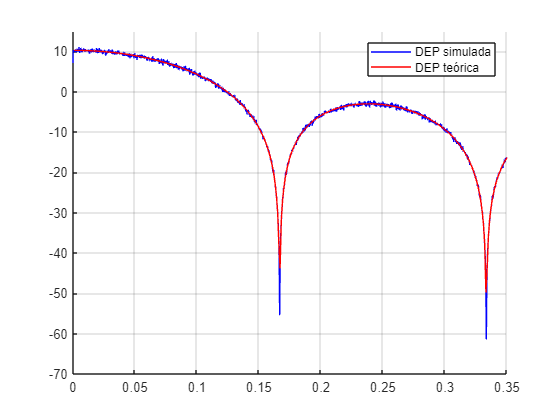

% replace this text with your code
RB = 1e-3;
figure

segmentL = n/RB;
[Pxx,F] = pwelch(yi, hamming(segmentL),segmentL/2,segmentL,n, 'onesided');

% DEP teórica
Pxx_t = Es .* ((sin(pi * F.*nbps)) ./ (pi * F.*nbps) ).^2;

hold on
plot(F/nbps, 10.*log10(Pxx), 'b'), xlim([0 0.35]), ylim([-70 15]);
plot(F(1:length(Pxx_t)), 10*log10(Pxx_t), 'r'), grid on
legend('DEP simulada', 'DEP teórica')
hold off

### Comments

Parameter justification

- O uso da função `pwelch `de modo a estimar a PSD unilateral do sinal em banda base ( yi );

- Os valores de saída` Pxx` e `F` correspondem à estimativa e às frequências correspondentes;

- `hamming(segmentL): j`anela de Hamming. Esta janela é aplicada ao sinal de modo a diminuir o vazamento espetral;

- `segmentL: `determina o equilíbrio entre a resolução de frequência e variância e a suavização da PSD; 

- `segmentL/2: `valor de sobreposição de 50% que ajuda na redução da variância na estimativa da PSD;

A DEP obtida mostra estar em conformidade com o a DEP teórica dando informações sobre a potência de sinal em banda fase em diferentes frequências.

***(g)  ***Obtain by simulation the unilateral PSD of the modulated carrier at the QAM transmitter output (signal E in Fig. 1). The frequencies scale must be normalized relative to the **transmission rate of the bits **transported by the QAM signal. The quality of the simulated PSD should obey the requirements defined in (f). The xx-axis scale must be chosen to allow viewing of the relevant part of the PSD. **Justify the numerical abscissa values **corresponding to the absolute maximum of the PSD, and the first two minima around this maximum. Draw **on the same graph** the corresponding theoretical curve. Comment on the results obtained.

Simulated and theoretical unilateral PSD

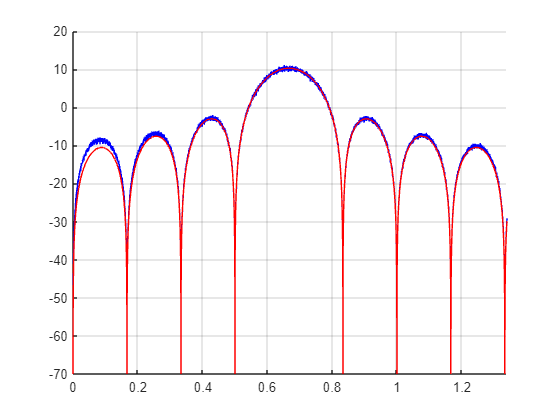

% replace this text with your code
n_t = (0:m*n)*nbps/n;
n_tt = n_t(1:end-1);

C_modulado = sqrt(2)*yi.*cos(2*pi*n_tt./nbps*Rfs);
D_modulado = sqrt(2)*yq.*sin(2*pi*n_tt/nbps*Rfs);

% DEP obtida
E_modulado = C_modulado + D_modulado;
[Pxx_mod,F_mod] = pwelch(E_modulado, hamming(segmentL),segmentL/2,segmentL,n, 'onesided');

Pxx_t_mod = E_sim*((sin(pi*(F-Rfs)))./(pi*(F-Rfs))).^2;
figure
hold on
plot(F_mod/nbps, 10.*log10(Pxx_mod), 'b'), xlim([0 1.34]), ylim([-70 20])

plot(F_mod/nbps, 10.*log10(Pxx_t_mod), 'r'), xlim([0 1.34]), ylim([-70 20]), grid on
hold off

### Comments

A DEP obtida do sinal complexo já centrado à frequência da portadora, ou seja, 4 vezes a frequência de símbolo.

Aqui encontramos o máximo absoluto da PSD. 

Para uma frequência de amostragem temos de 1 Hz/nbps onde `nbps = 6, `então o bit rate corresponderá de 0.1665 a 0.1665. Logos temos os primeiros nulos a (aproximandamente) 0.4998 Hz/nbps e a 0.8336 Hz/nbps.

## 3       System performance

**In this section, you must work exclusively in the signal constellation (baseband) domain. **

### *3.1*      *Implementation*

Develop a QAM system corrupted by Gaussian white noise, as shown in the following figure.

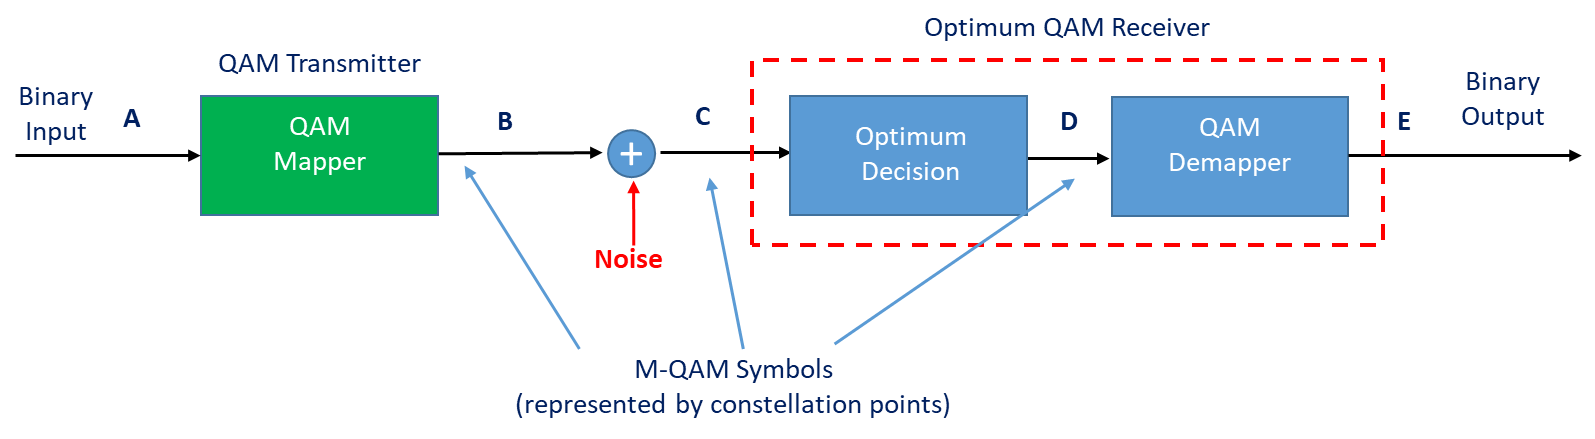

*Figure 3*

The block 'Optimum QAM Receiver' in Figure 3 must be a maximum likelihood receiver, i.e., it should minimize the distance between the vector representing the received signal (signal plus noise) and the set of signal vectors (no noise).

The mapping between the input bits and the QAM symbols (block 'QAM Transmitter' in Figure 3) is represented by the following matrix:

     M1_16QAM= [3   3  0 0 0 0;
	            3   1  0 0 0 1;
                3  -3  0 0 1 0;
	            3  -1  0 0 1 1;
	            1   3  0 1 0 0;
	            1   1  0 1 0 1;
	            1  -3  0 1 1 0;
	            1  -1  0 1 1 1;
 	           -3   3  1 0 0 0;
	           -3   1  1 0 0 1;
	           -3  -3  1 0 1 0;
               -3  -1  1 0 1 1;
	           -1   3  1 1 0 0;
	           -1   1  1 1 0 1
	           -1  -3  1 1 1 0
	           -1  -1  1 1 1 1];

Here the first two numbers in each row represent the components of a 16-QAM symbol, in the system of carriers $\left(\phi_1 ,\phi_2 \right)$ shown in Figure 2. The third to sixth numbers represent the information bits transported by the same symbol. This constellation has a normalized distance of 2 between contiguous symbols, so its elements must be multiplied by the appropriate constant to obtain the constellation with the required distance $d$.  

### *3.2*      *Verification*

***(a)***  Assuming that the noise ($n_0$) added by the transmission channel has a unilateral PSD of noise ($n_0$) of 1 dBm, calculate the distance between two contiguous constellation points (in volts) to obtain a theoretical probability of symbol error ($P_{es}$) equal to $10^{-2}$ at **point D** in Figure 3. **Show all the calculations done to obtain the distance value**.

**Suggestion**: use the following expression, valid for square QAM constellations of size $M=2k$, with $k
$ even:

$P_{es} = 1 - \left[1-\left(1-\frac{1}{\sqrt{M}}\right)\mathrm{erfc}\left(\sqrt{\frac{3 E_s}{2(M-1)n_0}}\right)\right]^2$    expression (1)

Where $E_s$ is the average energy per symbol. This energy is given by


$$E_s = (M-1)\frac{d^2}{6}$$


### Calculations

By manipulating expression (1) we obtain:     $E_s = n_o(M-1)\frac23{\left(erfcinv\left(\frac{1-\sqrt{1-P_{es}}}{1-\frac1\sqrt{M}}\right)\right)}^2$

Solving for:    $M = 16$;    $P_{es} = 10^{-2}$;    $n_o = \frac{10^{\left(\frac1{10}\right)}}{1000}$   (1dBm)

We obtain the following equation:        $E_s = 0.0126{\left(erfcinv\left(\frac{1-\sqrt{1-0.01}}{0.75}\right)\right)}^2$

And the following result

% replace this text with your code
M = 16;

no = 10^(1/10)/1000;

Pe = 10^-2;
Es1 = 0.0126*(erfcinv(0.0067))^2;
Es = no*(2/3)*(M-1)*(erfcinv((1-sqrt(1-Pe))/(1-(1/sqrt(M)))))^2

Es = 0.0463

Finally we use the second expression and solve for d:    $d = \sqrt{\frac{6E_s}{M-1}$

which, since its a 16-QAM, simplifies into: $d = \sqrt{\frac25Es}$

d1 = sqrt(6*Es/(M-1)); % expressão geral
d = sqrt(2/5*Es);      % sendo que se trata dum 16-QAM
fprintf("A distãncia entre pontos da constelação é d = %g", d);

A distãncia entre pontos da constelação é d = 0.136094

***(b)***    Using the values of parameters defined in (a), represent the full constellation corresponding to **point B** in Figure 3. **Represent also the information bits **corresponding to each point of the constellation. 

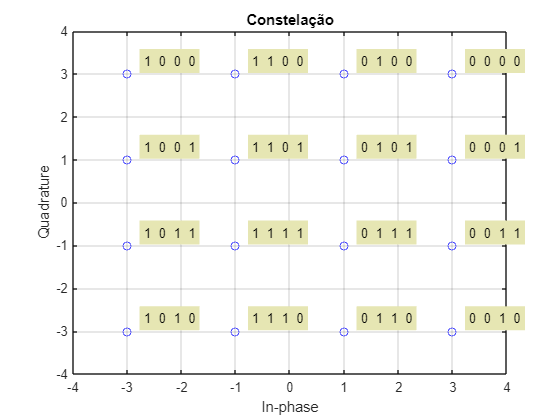

% replace this text with your code

levels = 4;
level = (-(levels - 1)*(d/2)):d:((levels - 1)*(d/2));

for j = 1:M
    t = [M1_16QAM(j,3) M1_16QAM(j,4) M1_16QAM(j,5) M1_16QAM(j,6)];
    str = num2str(t);
    plot(M1_16QAM(j,1), M1_16QAM(j,2), 'bo');
    text(0.3+M1_16QAM(j,1), 0.3+M1_16QAM(j,2), str,'BackgroundColor',[.9 .9 .7]);
    hold on
    grid on
end

xlim([-4 4]), ylim([-4 4]), title('Constelação'), xlabel('In-phase'), ylabel('Quadrature');

**Observations**

Por análise da matriz ( M1_16QAM ) verificamos que a constelação está bem construída.

**(c)** Plot a constellation with 1000 symbols at **point B (without noise)** of figure 3 represented by black circles ('ko'). In the same constellation depict the symbols obtained in **point C  (with noise)**, which should be represented by red dots. Comment on the results obtained.

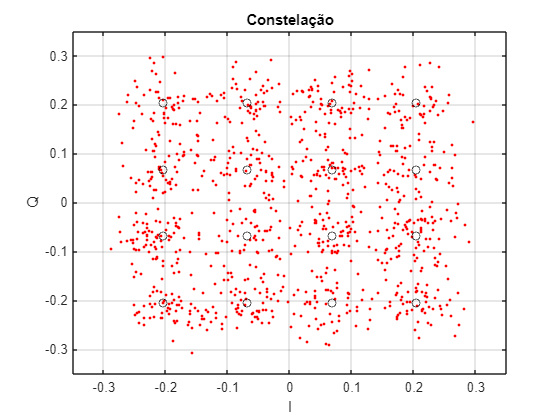

% replace this text with your code
m = 1000;

yi_B = mary(levels,double(d), m,1);
yq_B = mary(levels,double(d), m,1);

I_r = wgn(1, 1000, 1, 'dBm');
Q_r = wgn(1, 1000, 1, 'dBm');

I_com_ruido = I_r + yi_B;
Q_com_ruido = Q_r + yq_B;

hold on
plot(I_com_ruido(1:end), Q_com_ruido(1:end),'r.')
plot(yi_B(1:end), yq_B(1:end), 'ko')
grid on

ylim([-0.35 0.35]), xlim([-0.35 0.35]), title('Constelação'), xlabel('I'), ylabel('Q');

Observações:

A partir da constelação acima é possível verificar que para 1000 símbolos sem ruído coincidem com os valores da constelação, contudo, devido ao ruído na transmissão, os símbolos não são posicionados como os pontos ideais da constelação.

***(d)***  Considering the above conditions, draw (in the constellation) the simulated points of the first 4 transmitted symbols corresponding to **points B, C and D** in Figure 3.

Based only on observation of the graphical representation shown, can we conclude that for each one the four illustrated cases the receiver made a maximum likelihood detection? Detail the reasoning that lead to your conclusion.

Plot constellation 

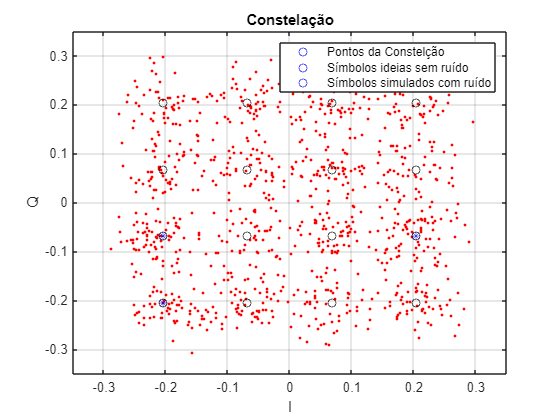

% replace this text with your code

plot(yi_B(1:end), yq_B(1:end), 'ko');
hold on
plot(yi_B(1:4), yq_B(1:4),'b*');
hold off
hold on
plot(I_com_ruido(1:4),Q_com_ruido(1:4), 'r.'); grid on
hold off
grid on, title('Constelação'), legend('Pontos da Constelção', 'Símbolos ideias sem ruído','Símbolos simulados com ruído'), xlabel('I'), ylabel('Q')

Comment

Com base na análise do gráfico, concluímos que o ML receiver está a funcionar como pretendido, corrigindo o sinal com ruído para o ponto da constelação mais próximo. Isto é, seguindo a minimização de distância ${||v-s_i||}^2$.

### 3.3 Performance metrics: SNR, EVM and BER      

From the simulated transmitted and received symbols estimate the following performance metrics and compare with the analytical results:

a) Energy per symbol ($E_s
$):

% replace this text with your code
% Valor teórico
M = 16;
Es_teorico = (M-1)*(d^2/6);
fprintf("Energia média (teórica) por símbolo é %g.", Es_teorico);

Energia média (teórica) por símbolo é 0.0463041.

Es_pratico = mean(yi_B.^2 + yq_B.^2);
fprintf("Energia média (prática) por símbolo é %g.", Es_pratico);

Energia média (prática) por símbolo é 0.0458967.

b)  Average noise power ($N_o$):

% replace this text with your code
No_teorico = 10^((1 - 30)/10 );
fprintf("No (teórico) é %g.", No_teorico);

No (teórico) é 0.00125893.

No_pratico = (mean(mean(sqrt((I_com_ruido - yi_B).^2 + (Q_com_ruido - yq_B).^2).^2)));
fprintf("No (prático) é %g.", No_pratico);

No (prático) é 0.00255747.

c) Signal-to-noise ratio (SNR) in dB:

% replace this text with your code

% teórico
SNR_teorico = 10*log10(Es_teorico/No_teorico);
fprintf("SNR (teórico) é %g.", SNR_teorico);

SNR (teórico) é 15.6562.

% prático
SNR_pratico = 10*log10(Es_pratico/No_pratico);
fprintf("SNR (prático) é %g.", SNR_pratico);

SNR (prático) é 12.5397.

d) Error vector magnitude (EVM) in dB defined as the average of root-mean-square (RMS) value of the difference between the received symbols and the transmitted (ideal) symbols.


$${\mathrm{EVM}}_{\mathrm{RMS}} \approx {\mathrm{SNR}}^{-\;\frac{1}{2}} ={\left(\frac{E_s }{N_o }\right)}^{-\;\frac{1}{2}}$$


% replace this text with your code

EVM_teorico = SNR_teorico^-(1/2);
fprintf("EVM (teórico) é %g.", EVM_teorico);

EVM (teórico) é 0.25273.

EVM_pratico = SNR_pratico^-(1/2);
fprintf("EVM (prático) é %g.", EVM_pratico);

EVM (prático) é 0.282395.

e) Using the simulated EVM and  expression presented in 3.2 a) calculate the $P_{es}
$*. ***Show all calculations leading to the value of *****Pes*****.**  The value obtained for $P_{es}
$ confirms the target value requested in 3.2 (a)? 

### **Calculations**

% replace this text with your code
Pes_teorico = 1-(1-((1-(1/sqrt(M))) * erfc(sqrt((3*Es_teorico)/(2*(M-1)*no)))))^2;
fprintf("Pes (teórico) é %g.", Pes_teorico);

Pes (teórico) é 0.01.

Pes_pratico = 1-(1-((1-(1/sqrt(M))) * erfc(sqrt((3*Es_pratico)/(2*(M-1)*no)))))^2;
fprintf("Pes (prático) é %g.", Pes_pratico);

Pes (prático) é 0.0103658.

### Comments

Os valores obtidos estão próximos dos valores teóricos. Também é de notar que o Pes calculado (1.03*10^-2) é muito próximo do Pes pretendido (10^-2) em 3.2. a).

### 3.4       Monte Carlo estimation of *Symbol and Bit Error rate*

**(a)** By using the Monte Carlo method estimate the Symbol Error Rate and compare it with the expected value.

Verify by simulation if the number of symbols/bits used in the simulation are sufficient to ensure that in 95% of the experiments the estimated error probability is within a factor of two of the real error probability.  

Monte Carlo estimation 

% replace this text with your code

No_dBm = 1;
No = 10^((No_dBm - 30) / 10)

No = 0.0013

[Pe_simb, Pe_bits]= MC(M,1000,M1_16QAM, No,d)

Pe_simb = 0

Pe_bits = 0

fprintf('Taxa de Erro de Símbolo: %g\n', Pe_simb);

Taxa de Erro de Símbolo: 0


fprintf('Taxa de Erro de Bits: %g\n', Pe_bits);

Taxa de Erro de Bits: 0


Comment

Método de Monte Carlo é um método probabilístico que explora a aleatoriedade neste sistema de modo a calcular a probabilidade de erro. Envolve a geração de amostras aleatórias de acordo com a distribuição de probabilidade associada ao sistema. Geramos símbolos, no caso 16-QAM, e, em seguida, adicionando ruído aleatório a esses símbolos.

Dado os resultados obtidos...

**(b)** Verify by simulation if the number of symbols/bits used in the simulation are sufficient to ensure that in 95% of experiments the estimated error probability is within a factor of two of the real error probability.  

% replace this text with your code

for i = 1:1000
    [Pe_simb, nada] = MC(M, 1000, M1_16QAM, No, d);
    % Armazene a estimativa da taxa de erro de símbolo
    result_pe_sim(i) = Pe_simb;
end
mean_Pe_sim= mean(result_pe_sim);
fprintf('Porbabilidade Média de Erro de Símbolo: %g\n', mean_Pe_sim);

Porbabilidade Média de Erro de Símbolo: 0.001166


**(c)** By using the Monte Carlo Simulation estimate the Bit Error Rate and compare it with the expected value.

% replace this text with your code

d) For the following constellation mapping and considering the same simulation parameters, estimate (by using the Monte Carlo Simulation) the Symbol and Bit Error Rate and compared with the previous results a) and c). Comment and justify the main differences:

      M2_16QAM= [ 1  1  0 0 0 0
	              3  3  0 0 0 1
                  1  -3 0 0 1 0
	             -1 -1  0 0 1 1
	             -1  3  0 1 0 0
	              3 -1  0 1 0 1
	             -3  3  0 1 1 0
	             -3  1  0 1 1 1
 	              3 -3  1 0 0 0
	             -3 -3  1 0 0 1
	              3  1  1 0 1 0
                  1  3  1 0 1 1
	             -1  1  1 1 0 0
	             -1 -3  1 1 0 1
	             -3 -1  1 1 1 0
	              1 -1  1 1 1 1 ];
    

d1) Represent the full constellation corresponding to **point B** in Figure 3. **Represent also the information bits **corresponding to each point of the constellation. Compare to the constellation obtained in 3.2 b)

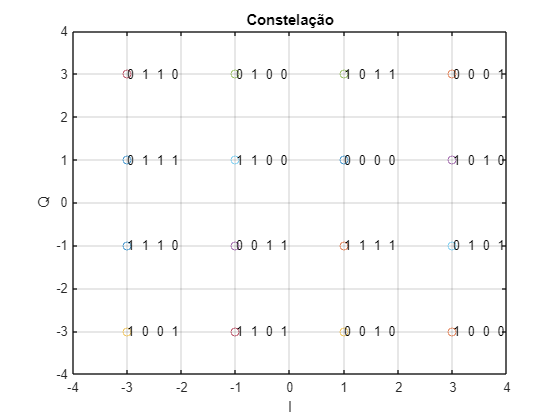

% replace this text with your code

levels = 4;
level = (-(levels - 1)*(d/2)):d:((levels - 1)*(d/2));

for j = 1:M
    t = [M2_16QAM(j,3) M2_16QAM(j,4) M2_16QAM(j,5) M2_16QAM(j,6)];
    str = num2str(t);
    plot(M2_16QAM(j,1), M2_16QAM(j,2), 'o');
    text(M2_16QAM(j,1), M2_16QAM(j,2), str);
    hold on
    grid on
end

xlim([-4 4]), ylim([-4 4]), title('Constelação'), xlabel('I'), ylabel('Q');
hold off

Comment

*"Replace this with your comments."*

d2) Estimate (by using the Monte Carlo Simulation) the Symbol and Bit Error Rate and compared with the previous results a) and c). Comment and justify the main differences:

% replace this text with your code

[Pe_simb_2, Pe_bits_2]= MC(M,1000,M2_16QAM, 1,d);
fprintf('Taxa de Erro de Símbolo: %g\n', Pe_simb_2);

Taxa de Erro de Símbolo: 0.004


fprintf('Taxa de Erro de Bits: %g\n', Pe_bits_2);

Taxa de Erro de Bits: 0.0025


Comment

*"Replace this with your comments."*

# 4      System performance

a) Consider the 16-QAM system studied in the previous sections, using the constellation mapping. Assume that the average symbol energy of the QAM signal is the same. Calculate the range of the noise PSD values [no_ini, no_end] dBm/Hz, where  these values originating probabilities of symbol error of $10^{-3}
$ and 0.4, respectively: To obtain no_ini and no_end use Eq (1)

% replace this text with your code
Pes_ini=1e-3; % Initial symbol Pe 
Pes_end=0.4;  % Final symbol Pe

d_i = sqrt(Es*6/(M-1))

d_i = 0.1361

%recurso à função qfunciv para trabalhar com Eq(1) nesta alinea
no_ini = ( d_i/ qfuncinv((1-sqrt(1-Pes_ini))/(2*(1-1/sqrt(16))))).^2 /2 ; 
no_ini_dbm = 10 * log10(no_ini / 0.001) 

no_ini_dbm = -0.9704

no_end=Es/((2/3)*(M-1)*(erfcinv((1-sqrt(1-Pes_end))/(1-(1/sqrt(M)))))^2);
no_end_dbm = 10*log10(no_end)+30

no_end_dbm = 9.3653

b) Determine by Monte Carlo simulation, the $P_{es}
$ and $P_{eb}
$ versus $E_b/n_0$ in dB for 10 values equally spaced of the noise PSD in the range [no_ini, no_end] dBm/Hz. The number of symbols used in simulation should be in accordance with the criterion described in the notes in the introduction. Present the results on a plot, where the yy axis must be on a logarithmic scale.

In the same graph, compare the $P_{es}
$ obtained analytically using expression (1) and also the approximation studied in the lectures given by:


$$P_e\simeq \frac{3}{2}\mathrm{erfc}\left(\frac{d}{2\sqrt{n_0}}\right) = \frac{3}{2}\mathrm{erfc}\left(\sqrt{\frac{\bar{E}}{10n_0}}\right)$$


Comment the results obtained.

Monte Carlo estimation

% replace this text with your code
no_10_dbm = linspace(no_ini_dbm, no_end_dbm, 10);
no_10_W= 10.^((no_10_dbm-30)./10);

Pe_teorico=1-[1-(1-1 /sqrt(M) )*erfc( sqrt( (3*Es) ./ ( 2*(M-1)*no_10_W ) ) )].^2;
Pe_aprox=(3/2)*erfc(sqrt(Es./(10*no_10_W)));
n_ciclos=1;

for i=1:10
    [Pe_simbMC, Pe_bitsMC]= MC(M,1000,M1_16QAM, no_10_dbm(i),d);
end

Eb_no = (Es./4) ./ no_10_W

Eb_no =    14.4744   11.1111    8.5294    6.5475    5.0261    3.8583    2.9618    2.2736    1.7453    1.3398


Eb_no = 10 .* log10(Eb_no)

Eb_no =    11.6060   10.4576    9.3092    8.1608    7.0123    5.8639    4.7155    3.5671    2.4187    1.2703


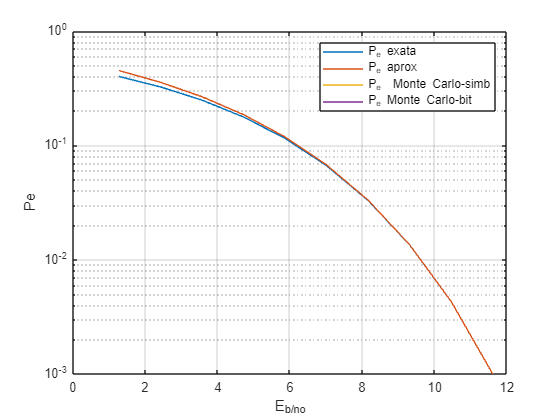

semilogy(Eb_no, Pe_teorico)
hold on
semilogy(Eb_no, Pe_aprox)
hold on
semilogy(Eb_no, Pe_simbMC)
hold on
semilogy(Eb_no, Pe_bitsMC,'k--')
grid on
legend('P_e exata', 'P_e aprox', 'P_e  Monte Carlo-simb', 'P_e Monte Carlo-bit')
ylabel('Pe')
xlabel('E_b/no')
hold off

Comment

*"Replace this with your comments."*

  c) Plot the ratio $P_{es}/P_{eb}
$ versus $E_b/n_0$ in dB, comment the results  

Plot the ratio $P_{es}/P_{eb}
$

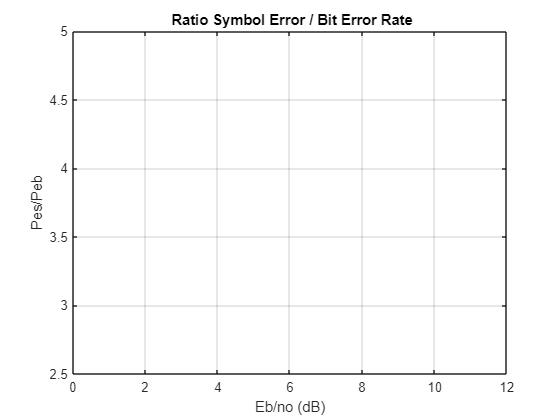

% replace this text with your code

ratio = Pe_simbMC./ Pe_bitsMC ;
plot(Eb_no, ratio)
title(' Ratio Symbol Error / Bit Error Rate')
grid on
xlabel('Eb/no (dB)');
ylabel('Pes/Peb');

Comment

*"Replace this with your comments."*

**Write the *****mary***** function here:**

function y= mary(levels,d,m,n)
% replace this text with your code
    level = (-(levels-1)*(d/2)):d:((levels-1)*(d/2)); % cria um vetor que contém os valores dos níveis possíveis para a amplitude dos símbolos com base no número de níveis e a distância etre os níveis
    x = randsrc(1,m,level); % gera valores aleatórios amostrados a partir dos níveis definidos em "level". Esses símbolos respresentam ao sinal de banda base.   
    y = [];
    for i = 1:m
        y = [y x(i)*ones(1,n)];
    end
end

% x(i)*ones(1,n) -> cria uma sequência de "n" amostras do mesmo sinal "x(i)".
% y: O resultado final é um sinal modulado "y", onde os símbolos de banda base são repetidos "n" vezes.


function [Pe_simb, Pe_bits]= MC(M,N_symb,M1_16QAM, No_dBm,d)
%ajustar outra vez os valores da matriz como na alinea 2.3 b)

    Mx_16QAM=M1_16QAM;
    Mx_16QAM(:,1)=Mx_16QAM(:,1)/2;
    Mx_16QAM(:,2)=Mx_16QAM(:,2)/2;

    yi_new= mary(4, double(d), 1000, 1);
    yq_new = mary(4, double(d), 1000, 1);

    I_ruido_novo = wgn(1, 1000, No_dBm-3, 'dBm');
    Q_ruido_novo = wgn(1, 1000, No_dBm-3, 'dBm');
   
    
    I_c_r_new = yi_new + I_ruido_novo;
    Q_c_r_new = yq_new + Q_ruido_novo;
    
    Sym_err = 0; Bit_err = 0;
    
    %gerar os valores simulados
    for j=1:N_symb 
        bit_diff = 0;
        for k=1:16
            %valor às 16 coordenadas da constelação e guardamos o valor das respetivas distancias ao novo simbolo
            distancia_com_ruido(k) = dist(I_c_r_new(j), Mx_16QAM(k, 1), Q_c_r_new(j), Mx_16QAM(k, 2)); % Testar a distância às 16 coordenadas com ruído    
             distancia_sem_ruido(k) = dist(yi_new(j), Mx_16QAM(k, 1), yq_new(j), Mx_16QAM(k, 2)); % Testar a distância às 16 coordenadas sem ruído  
        end

        %ver qual a menor distancia
        [nada,indice_min_com_ruido] = min(distancia_com_ruido);
        [nada,indice_min_sem_ruido] = min(distancia_sem_ruido);

        %condição de igualdade do simbolo suposto com o simbolo com ruido de menor distancia
         if( indice_min_sem_ruido ~= indice_min_com_ruido) 
             Sym_err = Sym_err + 1;

             %os bits do simbolo de menos distancia
             bits_min_com = [Mx_16QAM(indice_min_com_ruido, 3:6)];
             bits_min_sem = [Mx_16QAM(indice_min_sem_ruido, 3:6)];
             
             %comparar
             for n=1:4
                if( bits_min_com(n) ~= bits_min_sem(n) )
                    bit_diff = bit_diff + 1;
                end
             end
         end
         
         Bit_err = Bit_err + bit_diff;
    end
            
    Pe_simb = Sym_err/1000 ;
    Pe_bits = Bit_err/(4*1000) ;
    
    function dist = dist(i1, i2, q1, q2) % funcao para calculo da distancia
        dist = sqrt( (i2 - i1).^2 + (q2 - q1).^2 );
    end
end

     